%get data
%load('C:\Users\satur\OneDrive - University of Kansas\MATLAB\Ignition_video.mat')
load('C:\Users\satur\OneDrive - University of Kansas\MATLAB\ignitionCropped.mat')

% U_Z0_VER_Run1: longitudinal velocity
% V_Z0_VER_Run1: vertical velocity
% axeX_Z0: x-coordinates of data points
% axeY_Z0: y-coordinates of data points
% Nt: number of snapshots

% Reshape into meshgrid standard (not my code)
% U_raw & V_raw are of the from S(i,j,k)
% where i is the y-position in the field of view
% j is the x-position
% k is the snapshot index
% One snapshot was taken every 1.1 milliseconds (fs = 900 Hz).
% X_raw = axeX_Z0';
% Y_raw = flipud(axeY_Z0-axeY_Z0(1,1))';
% U_raw = permute(U_Z0_VER_Run1, [2,1,3]);
% V_raw = permute(V_Z0_VER_Run1, [2,1,3]);

% Undersample every 3 points (x and y change; t stays the same) (not my code)
% because my computer is not very fast
% X = X_raw(1:3:end,1:3:end);
% Y = Y_raw(1:3:end,1:3:end);
% SU = U_raw(1:3:end,1:3:end,:); %SU longitudinal velocity snapshot matrix
% SV = V_raw(1:3:end,1:3:end,:); %SV verticle velocity snapshot matrix

% % Undersample every 2 points (not my code)
% % because my computer is not very fast
% X = X_raw(1:2:end,1:2:end);
% Y = Y_raw(1:2:end,1:2:end);
% SU = U_raw(1:2:end,1:2:end,:); %SU longitudinal velocity snapshot matrix
% SV = V_raw(1:2:end,1:2:end,:); %SV verticle velocity snapshot matrix


videoFrames = double(videoFrames(1:5:end,1:5:end,:,:)); %5 works. 2 is pushing it
% greyVideoFramesG = double(squeeze(greyVideoFrames(1:3:end,1:3:end,2,1:3:end)));
% greyVideoFramesB = double(squeeze(greyVideoFrames(1:3:end,1:3:end,3,1:3:end)));
%size(videoFrames)


%initialize things
%mode = 1;
%SU %works
POD = ProperOrthogonalDecomposerVersion2(videoFrames);
%POD = ProperOrthogonalDecomposer(U_raw); %bad: uses more memorry than I
%have ram TODO: re implement useing the sexy methos that only calculates on side
%POD.print
% POD.timeCoefficients
% POD.spatialModes
%POD.meanMatrix


## Reconstruction and Visulization

operating timesnap 1

raw data

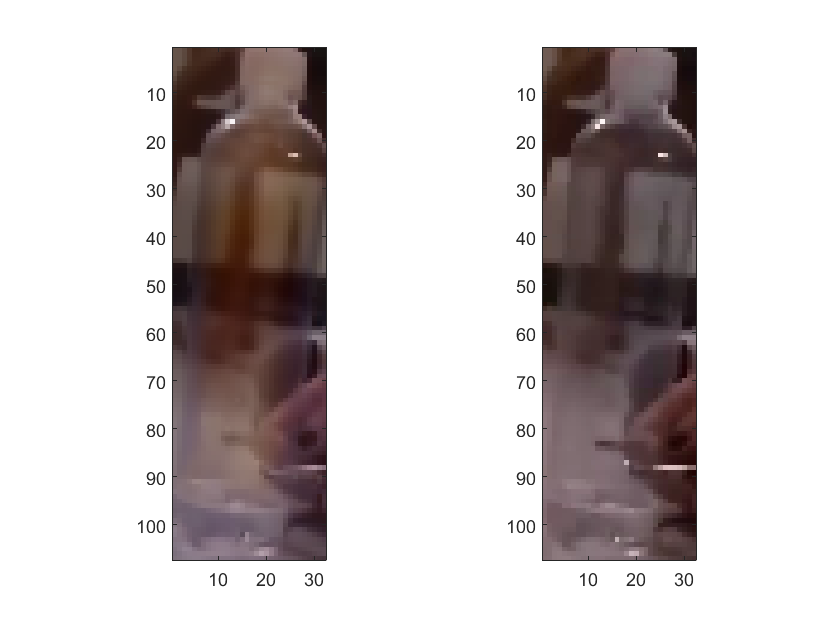

operating timesnap 2

raw data

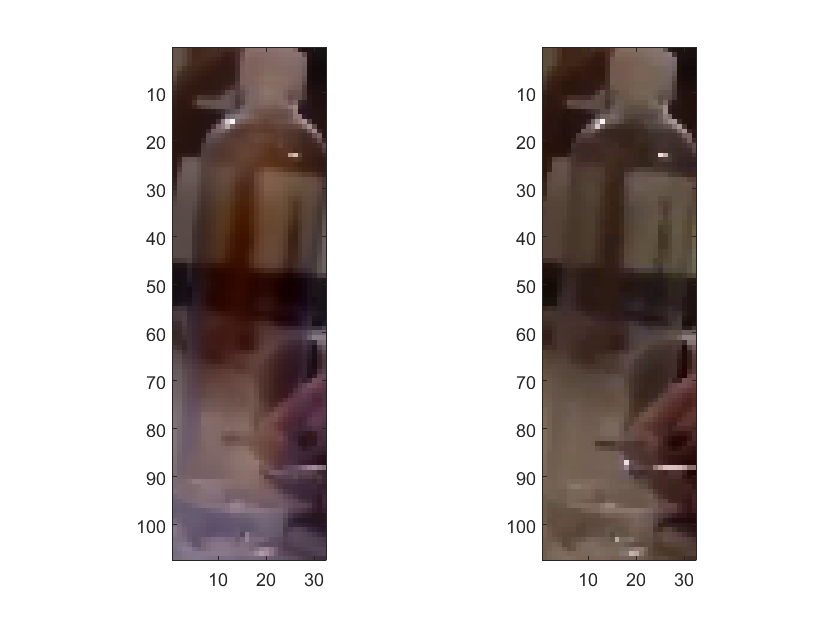

operating timesnap 3

raw data

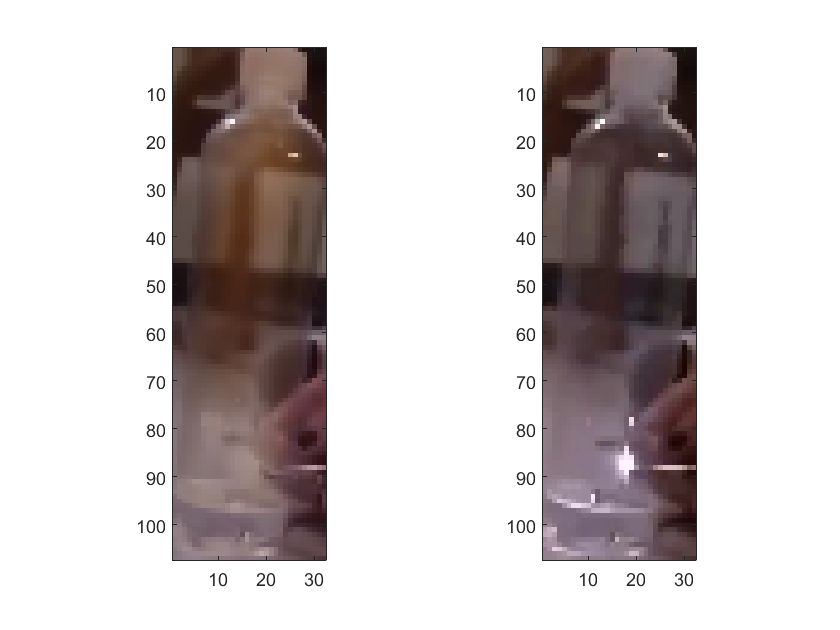

operating timesnap 4

raw data

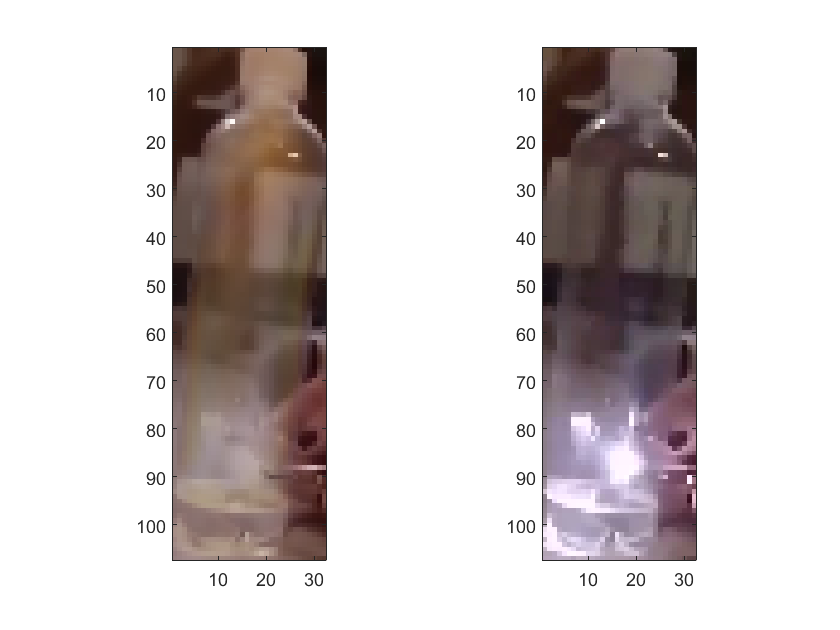

operating timesnap 5

raw data

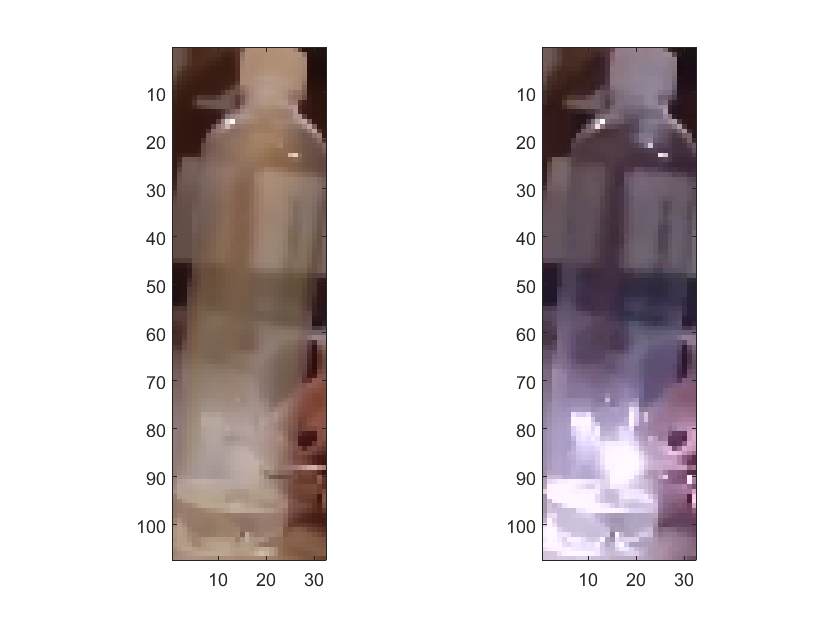

operating timesnap 6

raw data

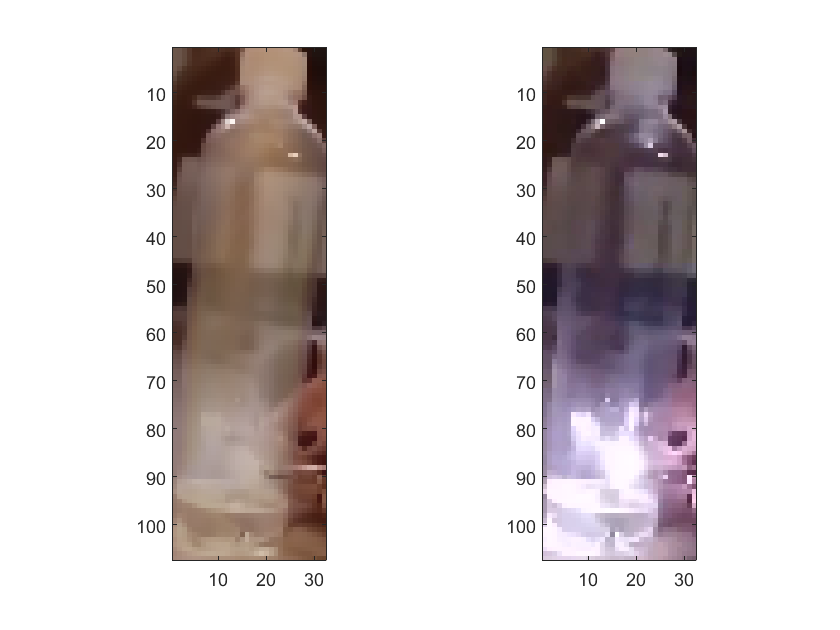

operating timesnap 7

raw data

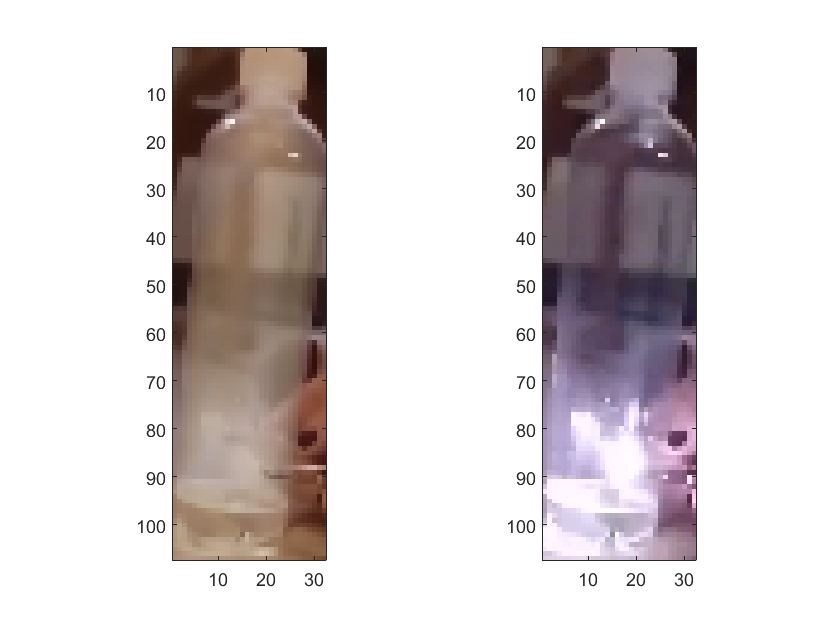

operating timesnap 8

raw data

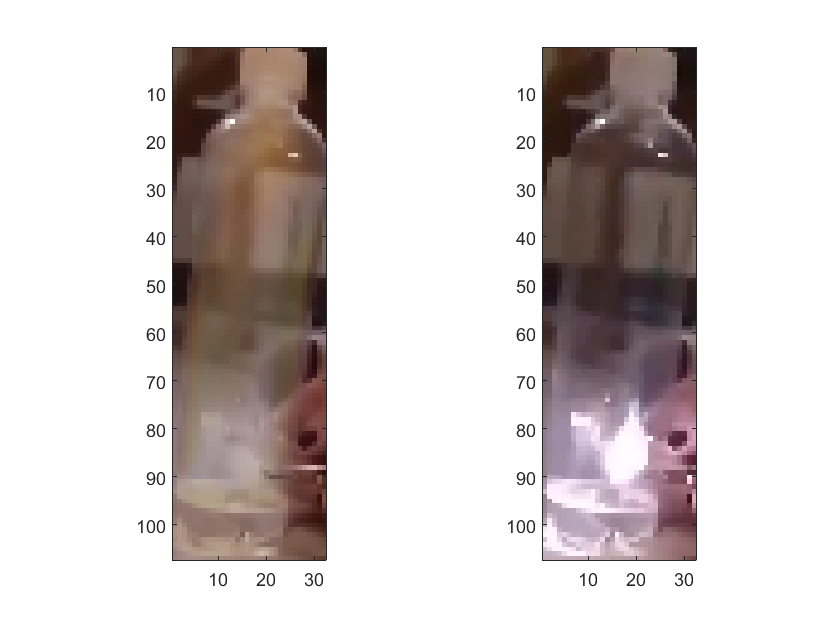

operating timesnap 9

raw data

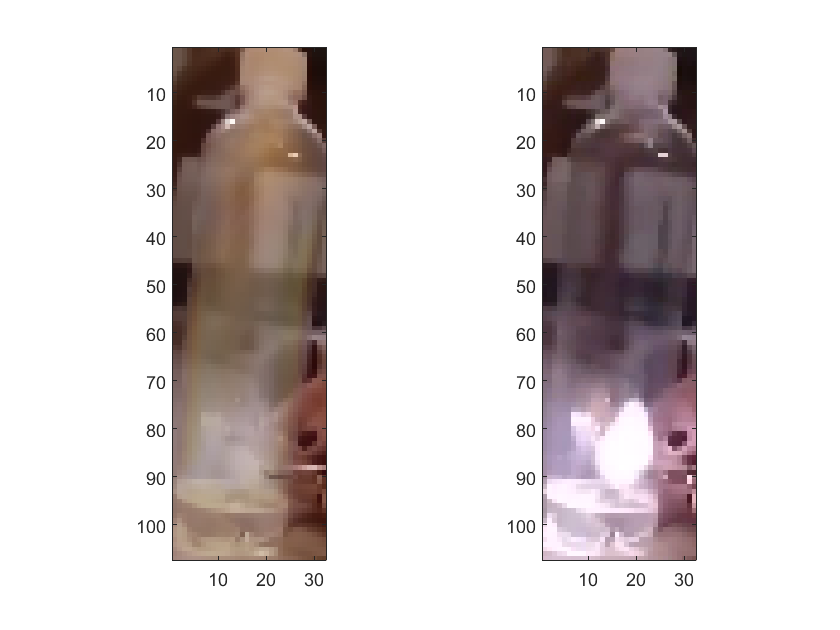

operating timesnap 10

raw data

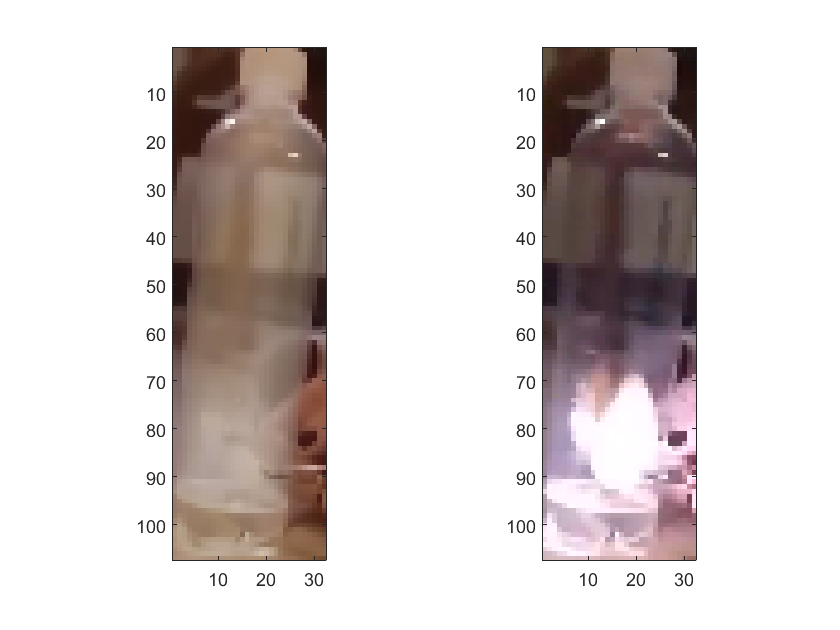

operating timesnap 11

raw data

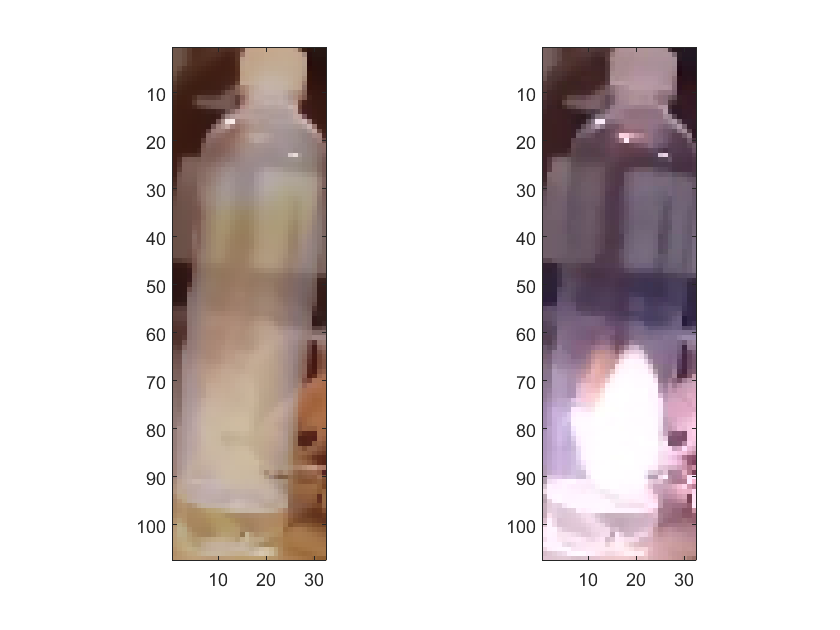

operating timesnap 12

raw data

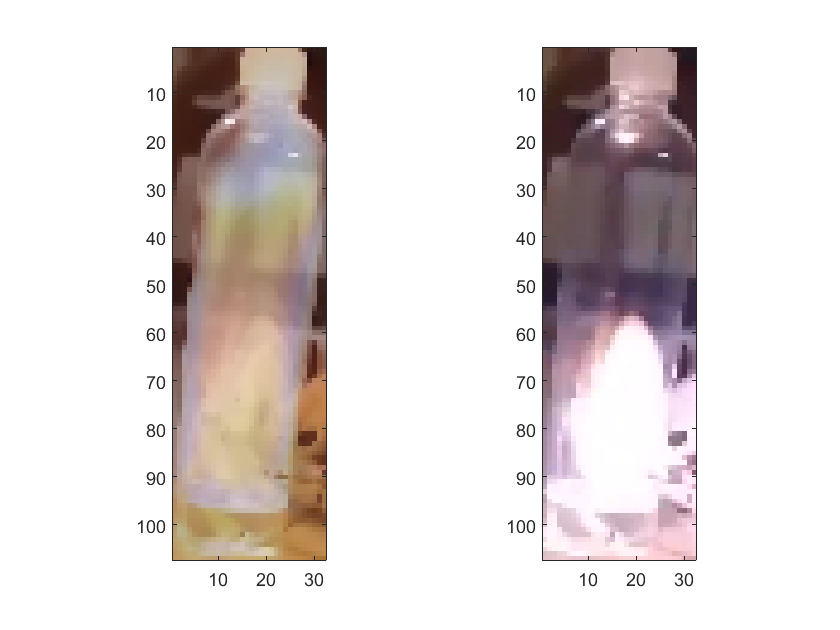

operating timesnap 13

raw data

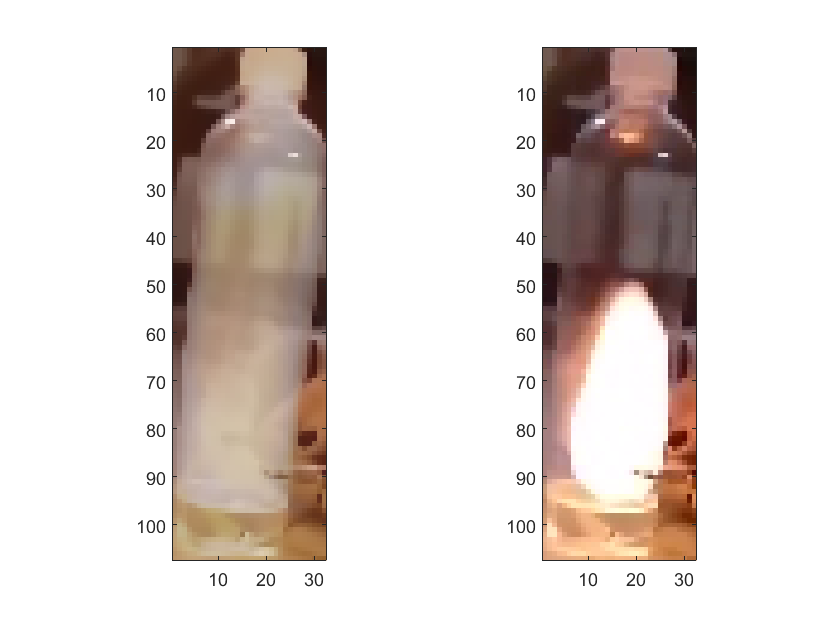

operating timesnap 14

raw data

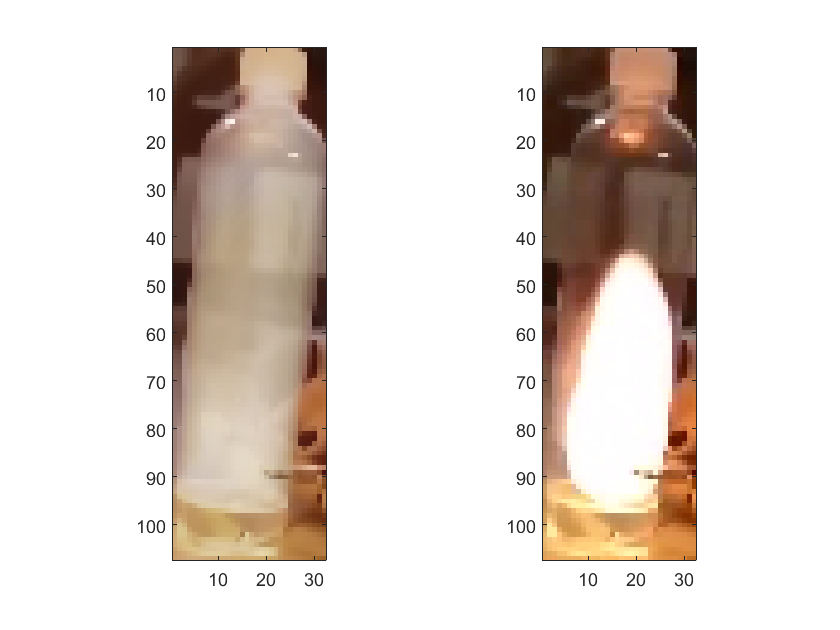

operating timesnap 15

raw data

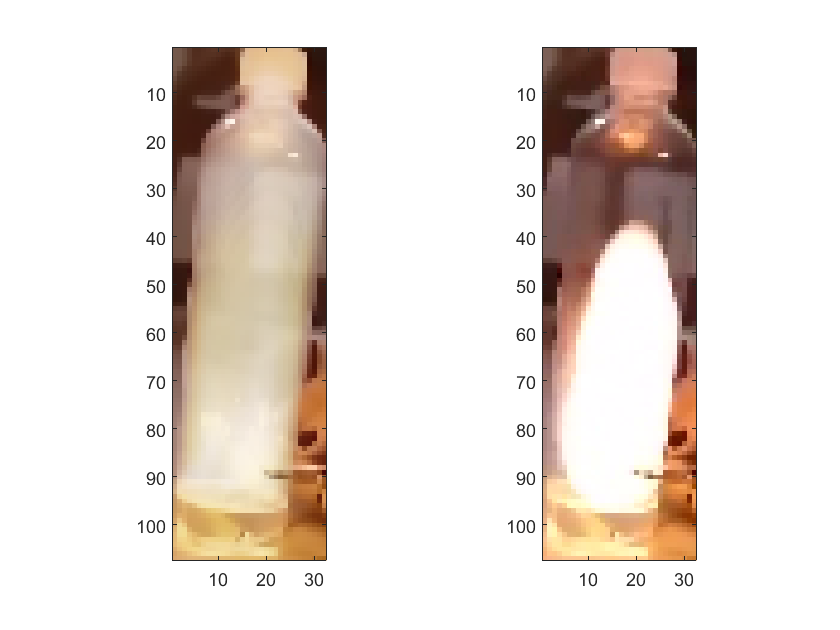

operating timesnap 16

raw data

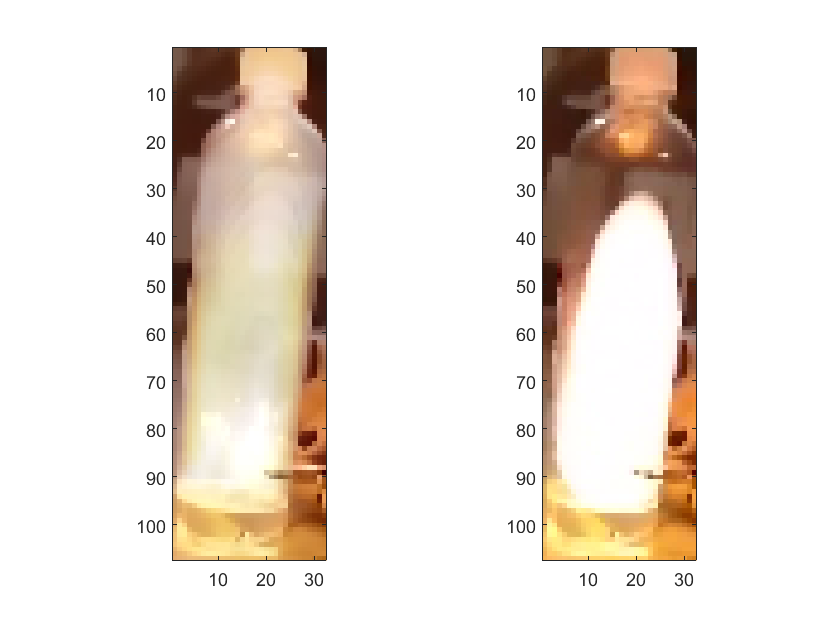

operating timesnap 17

raw data

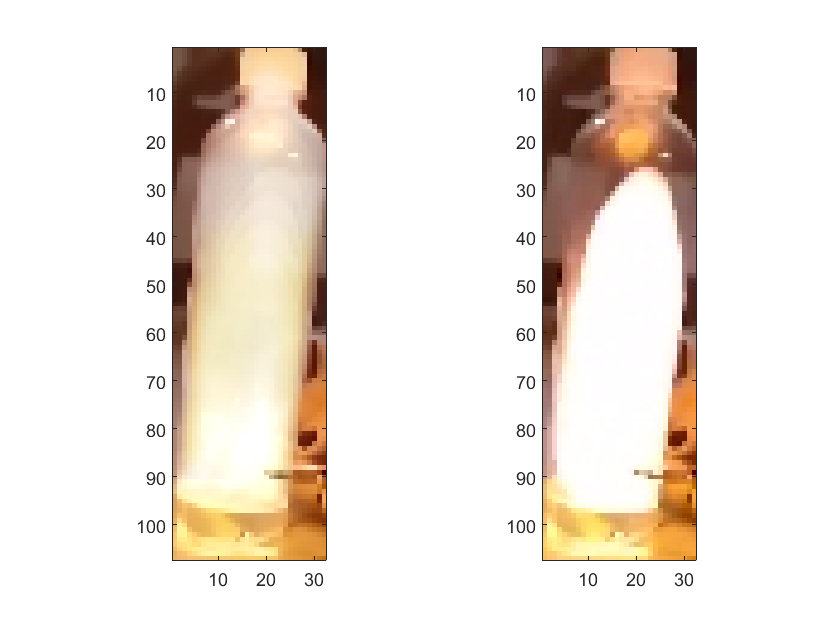

operating timesnap 18

raw data

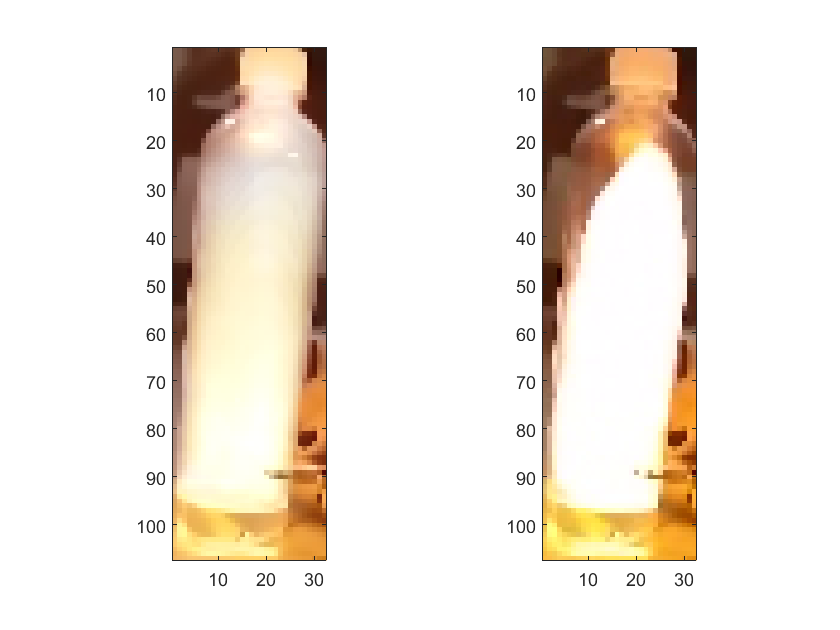

operating timesnap 19

raw data

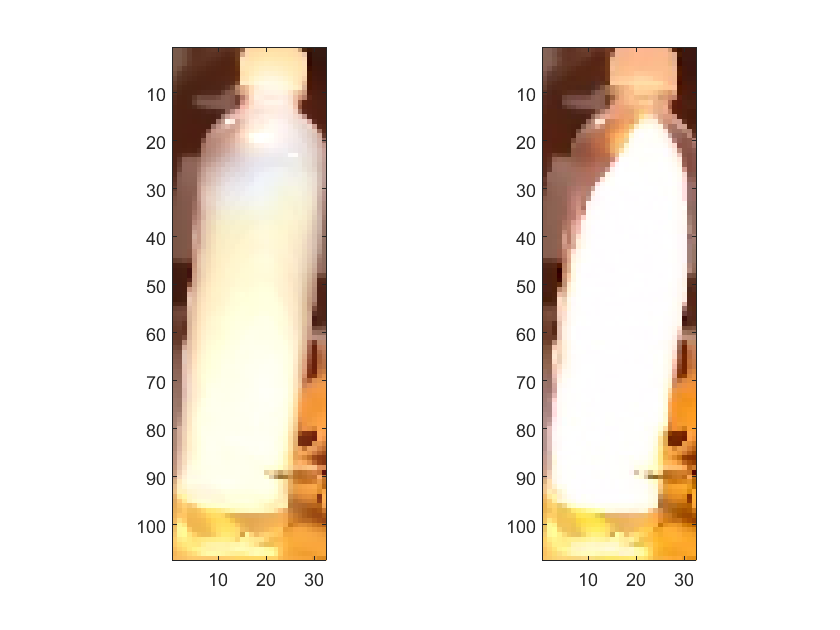

operating timesnap 20

raw data

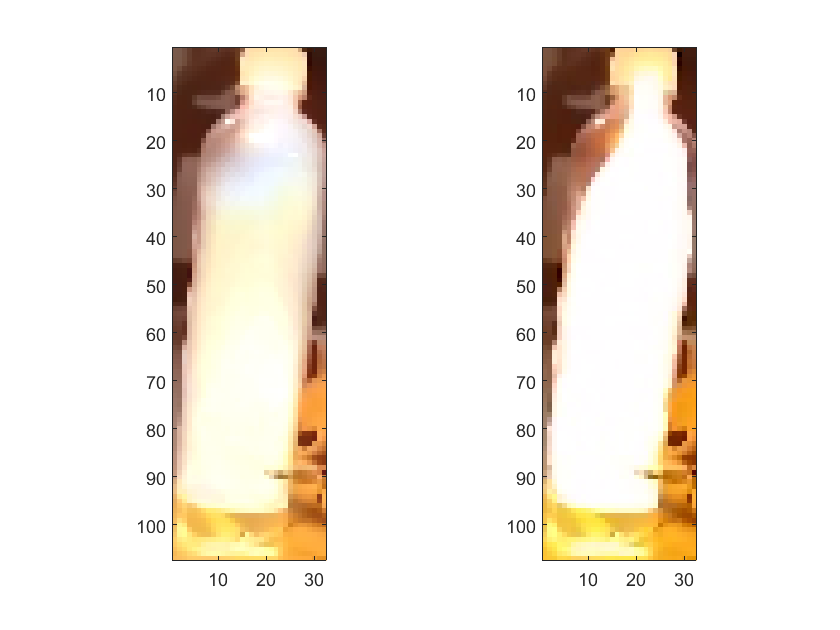

operating timesnap 21

raw data

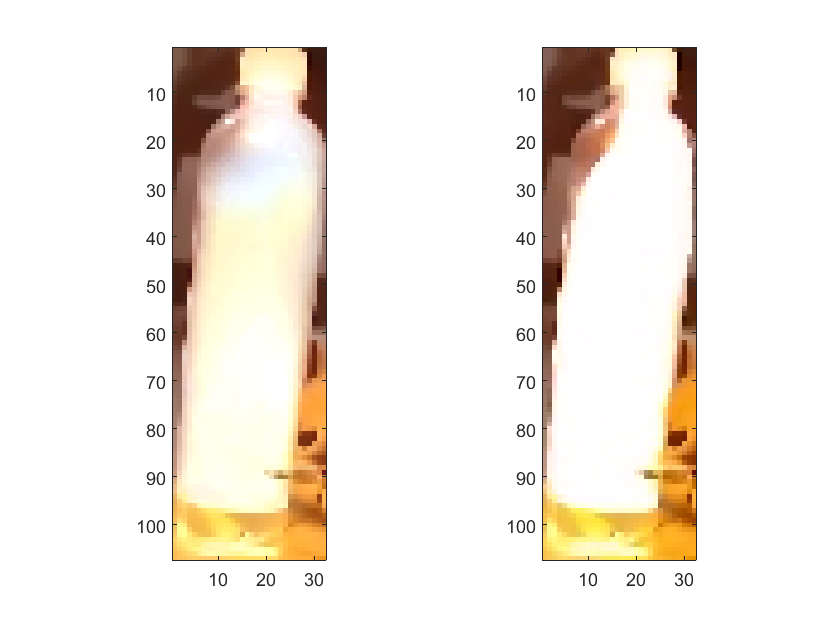

operating timesnap 22

raw data

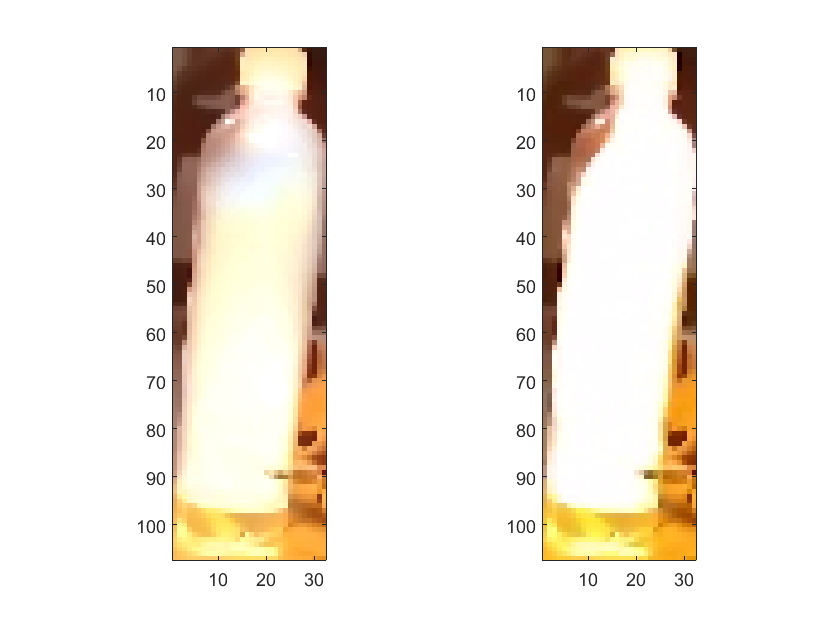

operating timesnap 23

raw data

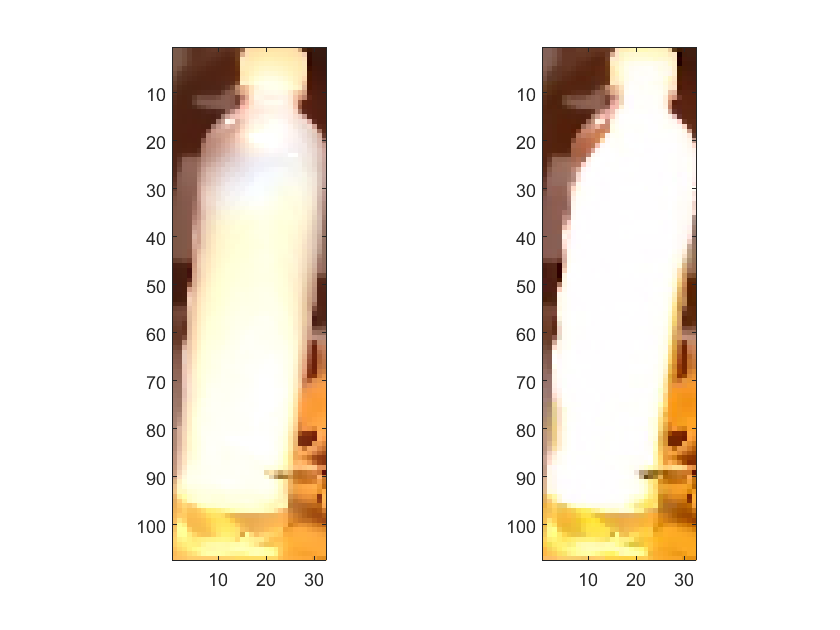

operating timesnap 24

raw data

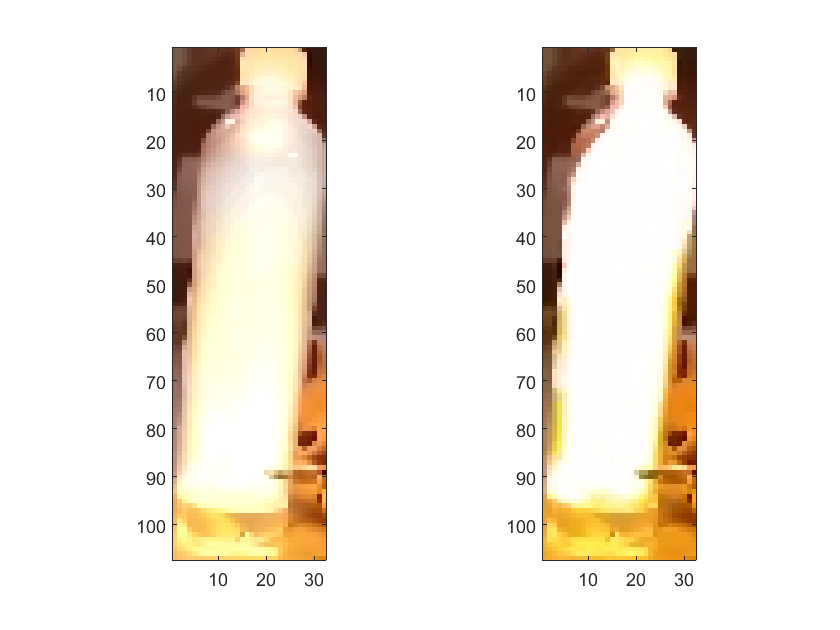

operating timesnap 25

raw data

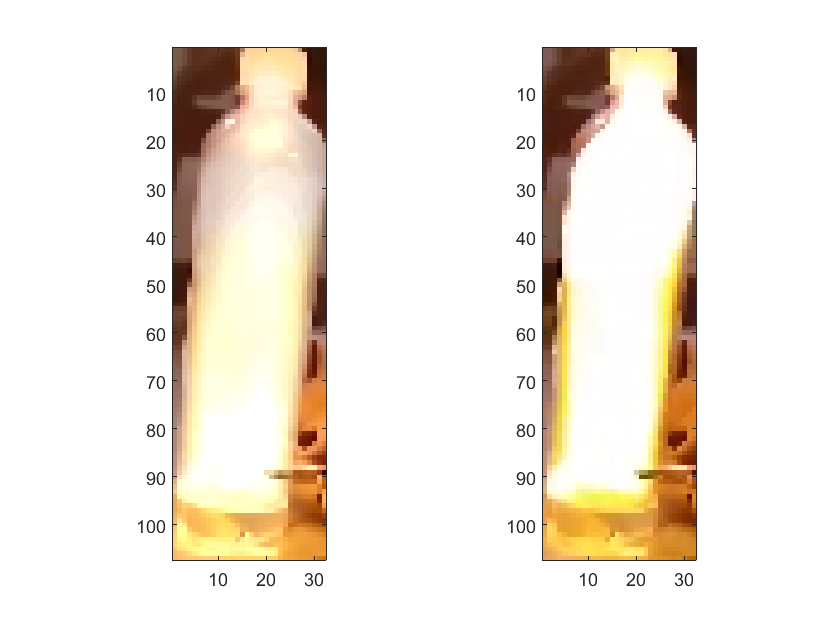

operating timesnap 26

raw data

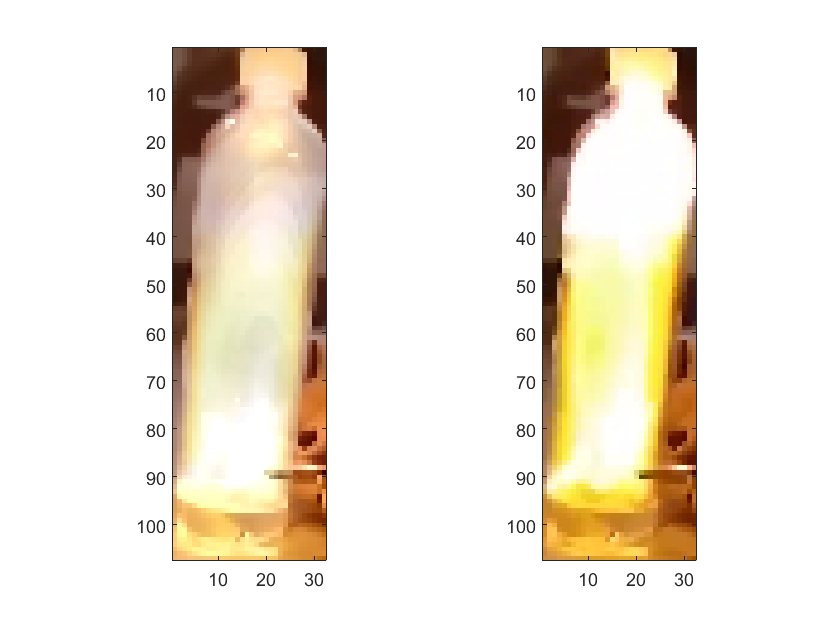

operating timesnap 27

raw data

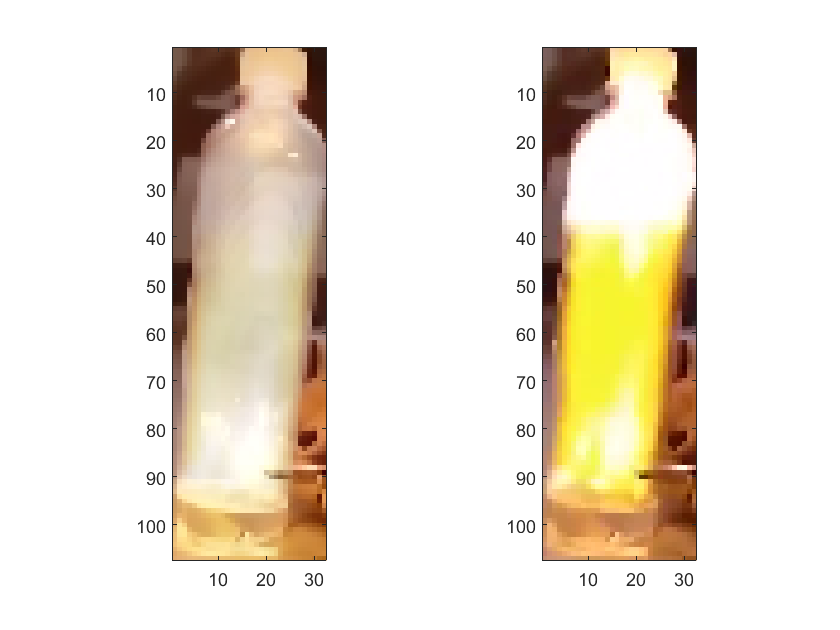

operating timesnap 28

raw data

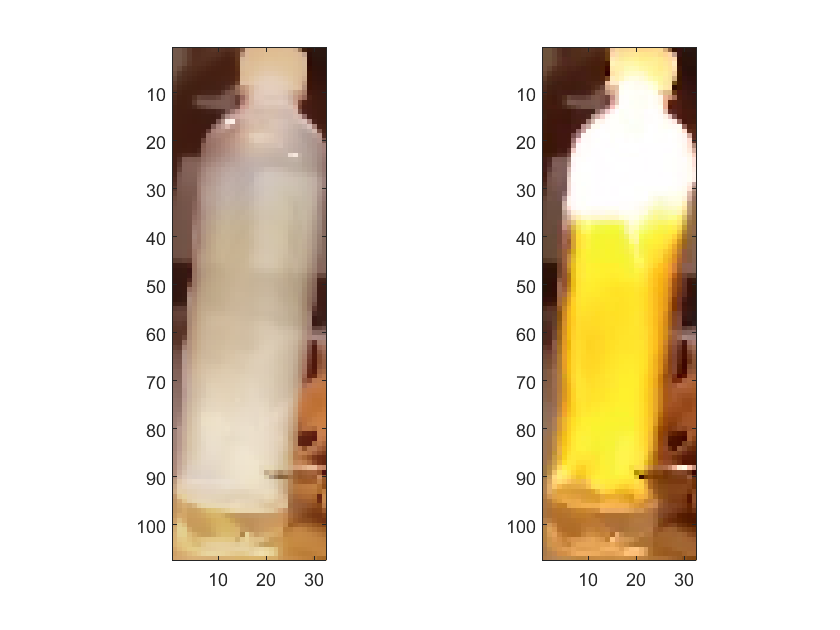

operating timesnap 29

raw data

operating timesnap 30

raw data

operating timesnap 31

raw data

operating timesnap 32

raw data

operating timesnap 33

raw data

operating timesnap 34

raw data

operating timesnap 35

raw data

operating timesnap 36

raw data

operating timesnap 37

raw data

operating timesnap 38

raw data

operating timesnap 39

raw data

operating timesnap 40

raw data

operating timesnap 41

raw data

operating timesnap 42

raw data

operating timesnap 43

raw data

operating timesnap 44

raw data

operating timesnap 45

raw data

operating timesnap 46

raw data

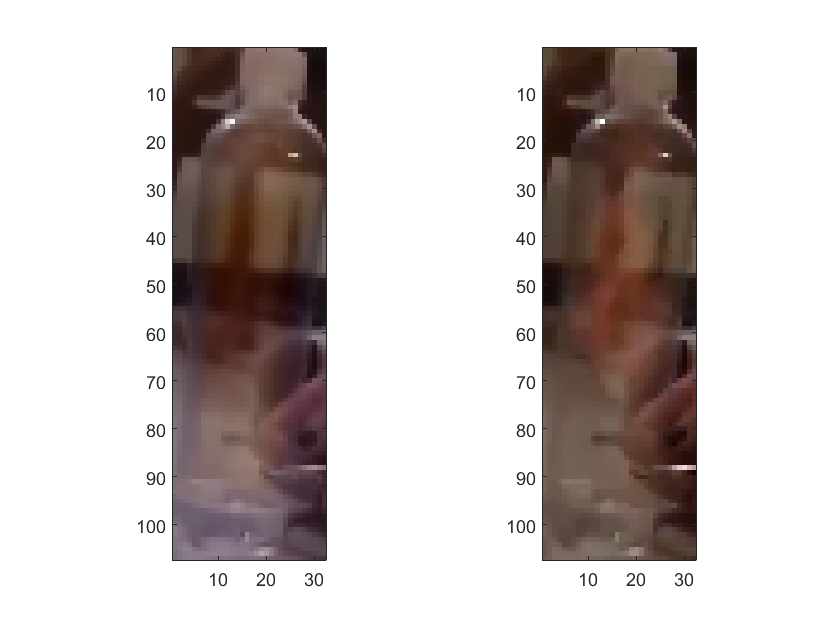

operating timesnap 47

raw data

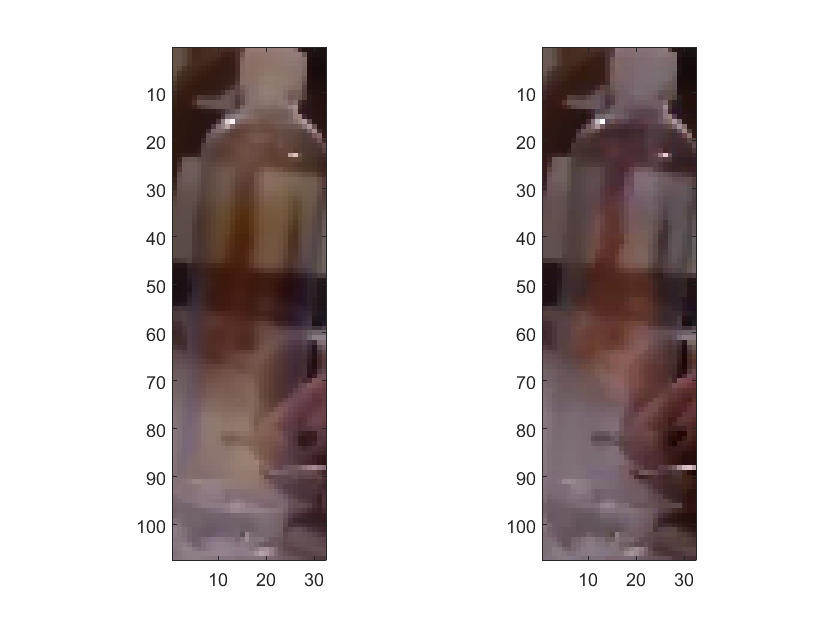

operating timesnap 48

raw data

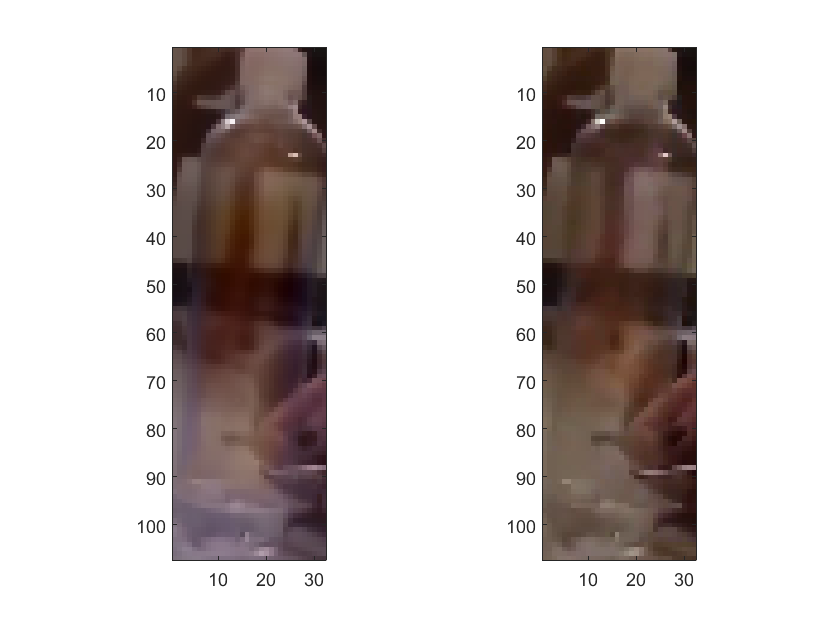

operating timesnap 49

raw data

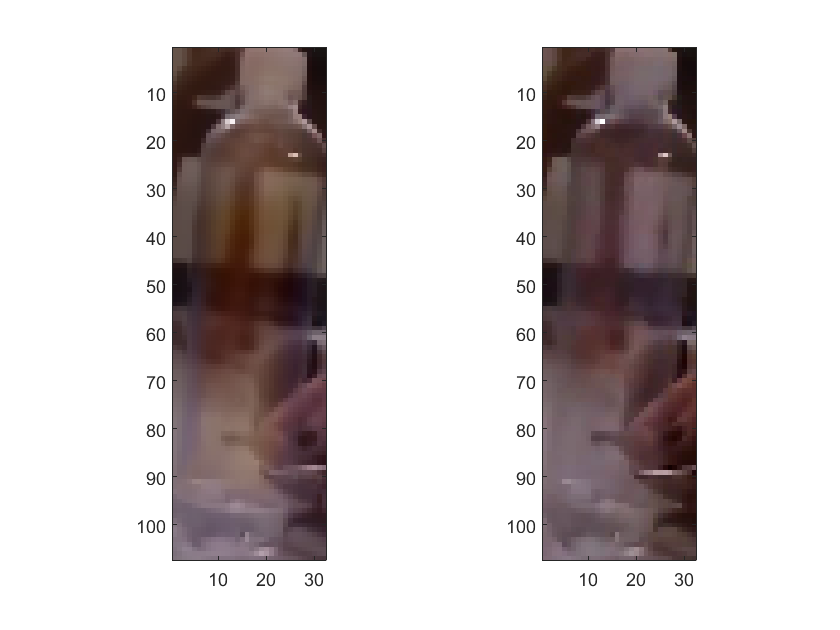

operating timesnap 50

raw data

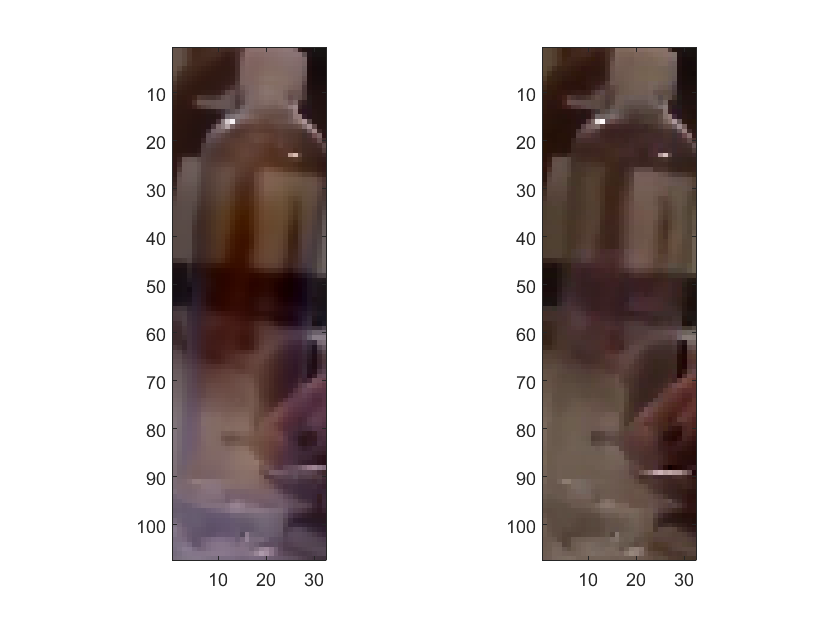

operating timesnap 51

raw data

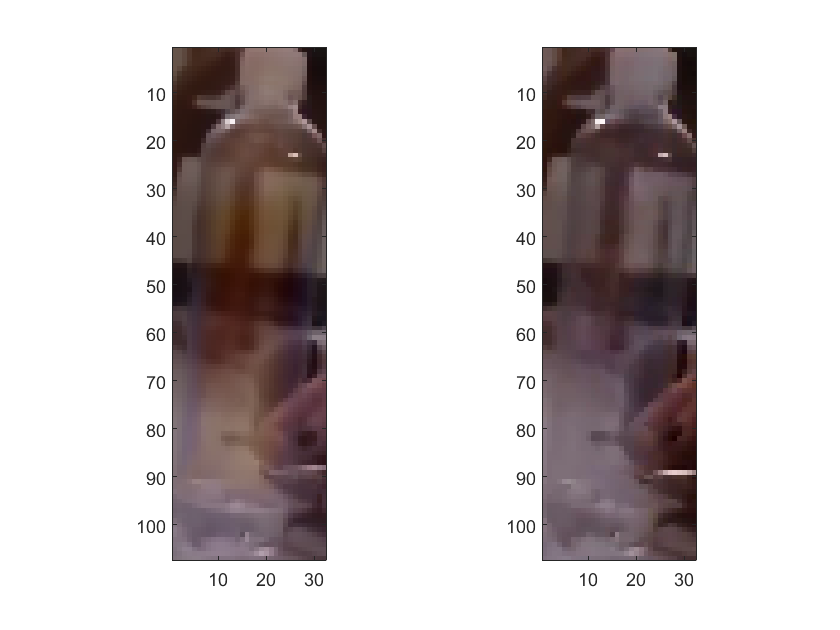

operating timesnap 52

raw data

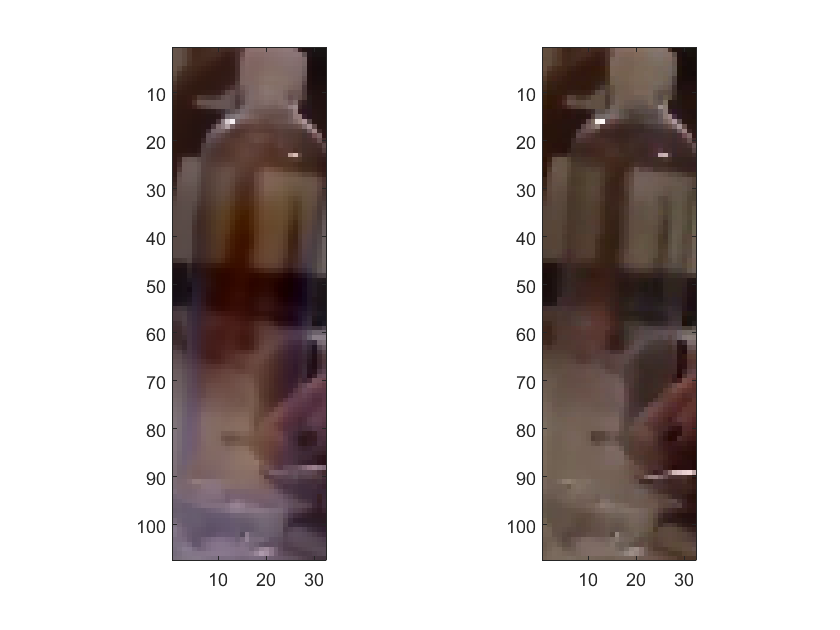

operating timesnap 53

raw data

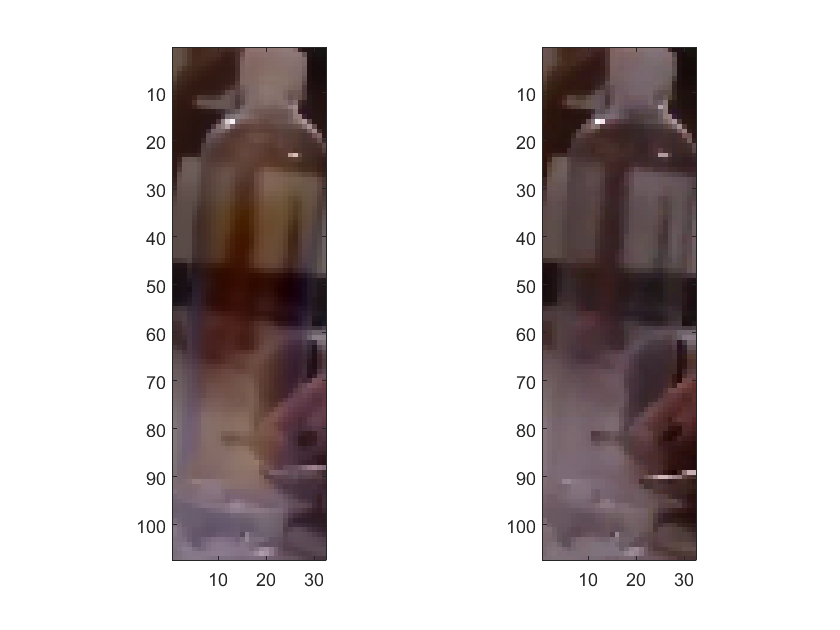

operating timesnap 54

raw data

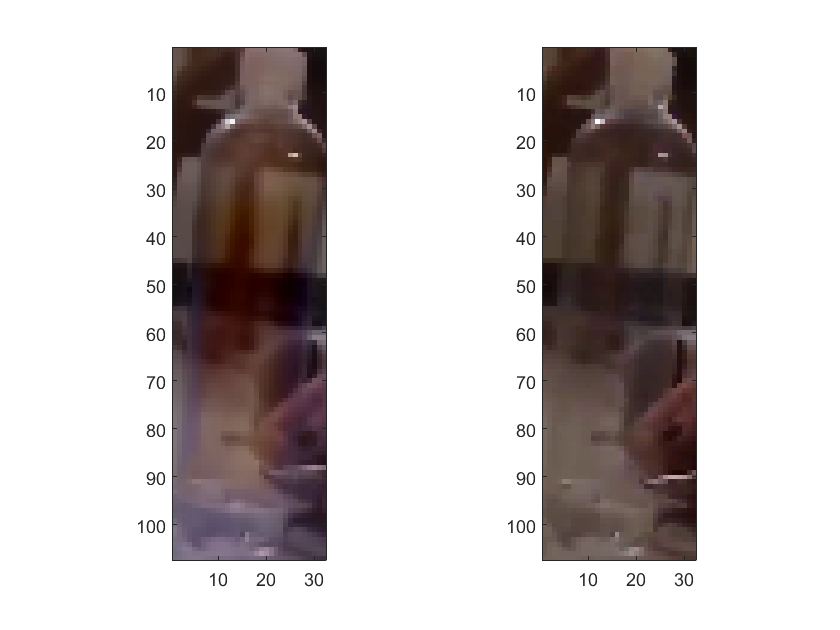

operating timesnap 55

raw data

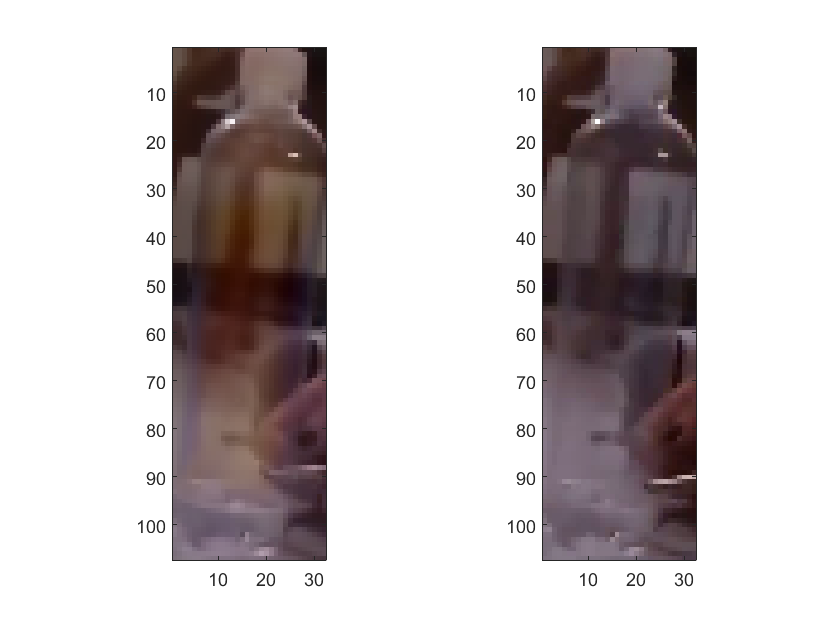

%TODO: VISUALIZE THE MODES BY REORDERING MODE PHI INTO AN IMAGE JUST LIKE
%i DO WITH SNAPSHOT TO DATMATRIX BUT ONLY IN 2D and I probably shouldn't
%restore the mean to them before i do it would be best to then present this
%data as done in figure 11 of the paper with the modes one one side in
%desending order and their assoiated time coefficients on the other side

%timeSnap = 1;
maxTimeSnap = 55; %maximum is 55
%timeStep = 5;

U_tilde_One = POD.reconstruct(1);
meanRestoredModeOne = POD.getMeanRestoredSnapshotMatrix(U_tilde_One);
meanRestoredModeOne_formatted = POD.restoreFormat(meanRestoredModeOne); 
currentModel = meanRestoredModeOne_formatted;
%modeOne_formatted = POD.restoreFormat(U_tilde_One); 

timeItteration = 1;

%M = [maxTimeSnap/timeStep];


%setup movie record
% h = figure;
% axis tight manual
% ax = gca;
% ax.NextPlot = 'replaceChildren';
% loops = maxTimeSnap/timeStep;
% 
% %M(loops) = struct('cdata',[],'colormap',[]);
% M = moviein(loops);
% h.Visible = 'off';

%initialize for parfor loop
%currentModel_k = struct([]);

%width = (0.815*129/45);

maxMode = 7; %7 is the largest number of modes with visably coherent structures

for timeSnap = 1:maxTimeSnap
%parfor timeSnap = 1:maxTimeSnap

%     fprintf('current model including mode 1 at t= %i',timeSnap)
%     figure
%     heatmap(currentModel(:,:,timeSnap));
%     grid off

    
    fprintf('operating timesnap %i',timeSnap);
    
    for mode = 2:maxMode %note to self: dont run up to 100 it is pointless (obviously)

        U_tilde_k = POD.reconstruct(mode);
        

        % figure
        % heatmap(U_tilde_k)
        % grid off

        %meanRestoredModek = POD.getMeanRestoredSnapshotMatrix(U_tilde_k);

        %restore formatting
        %meanRestoredModeOne_formatted = POD.restoreFormat(meanRestoredModek);
        modeK_formatted = POD.restoreFormat(U_tilde_k);

        %visualize

%           fprintf('timeSnap of mode %i',mode)
%           figure
%           heatmap(modeK_formatted(:,:,timeSnap));
%           grid off

        currentModel_k = currentModel + modeK_formatted;

%         fprintf('current model including mode %i at t= %i',mode,timeSnap)
%         figure
%         heatmap(currentModel(:,:,timeSnap));
%         grid off
        
        %heatmap(meanRestoredModeOne_formatted(:,:,2));
        %grid off
    end

    %visualize for video
    %fprintf('current model including mode %i at t= %i',maxMode,timeSnap);
    figure
    subplot(1,2,1);
    subimage(uint8(currentModel_k(:,:,:,timeSnap)))
%     heatmap(currentModel_k(:,:,timeSnap));
%     grid off;
%     colormap default;
%     caxis([0,255]);
    %h.InnerPosition(.13, .11,  0.717857142857143, width);
    %drawnow;

    %visualize
    fprintf("raw data");
%     figure % leave this commented so video works

     subplot(1,2,2);
     subimage(uint8(videoFrames(:,:,:,timeSnap)))
    
    
    
    
%     image(videoFramesR(:,:,timeSnap));
%     grid off
%     colormap default;
%     caxis([0,255]);
    %foo = getframe(gcf);
    
    M(timeSnap) = getframe(gcf); %(currentModelFigure);
    %M(timeItteration) = getframe(gcf); %(currentModelFigure);



    %timeItteration = timeItteration + 1;
end


% h.Visible = "on";
figure;

%save movie - currently doing debug of pod

moviePlayer = VideoWriter('RGB_Ignition_Cropped_POD_video_modified','MPEG-4');

moviePlayer.FrameRate = 20;
open(moviePlayer);
writeVideo(moviePlayer,M);
close(moviePlayer);
